# **Advanced Wireless Communications**

**Homework 2**

**Mahnoor Anjum (Reg #330720)**

**Date Assigned:**  **March 21, 2021**

**Due Date: March 31, 2021**

## **Problem 1**: 

Plot and compare the path loss (dB) for the free-space and flat specular surface models at 800 MHz versus distance on a log-scale for distances from 1 m to 40 km. Assume that the antennas are isotropic and have a height of 10 m. (Use the sinusoidal path loss equation on page 28 Lecture 4 for simulating the flat surface model) 

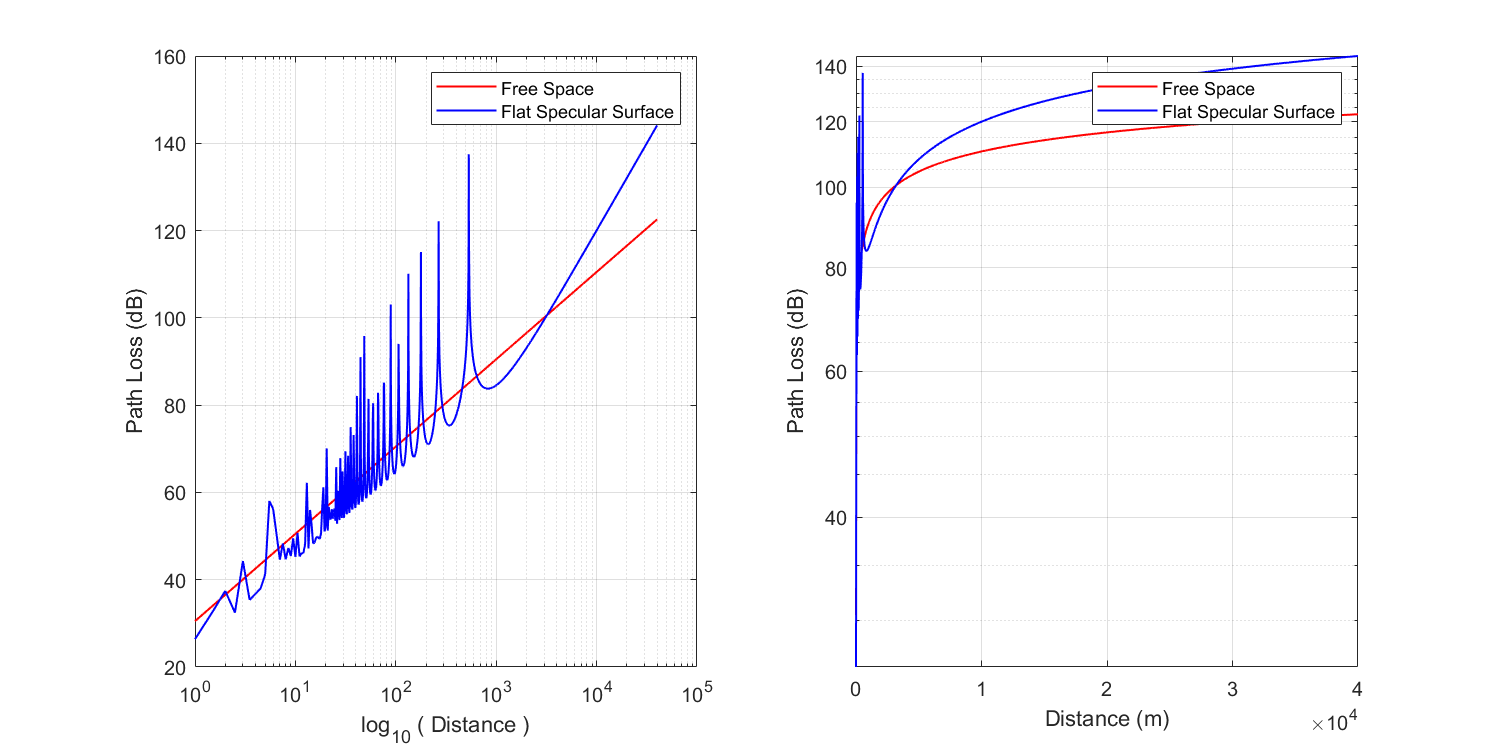

freq = 800*10^6; %Hz
lambda = physconst('LightSpeed')/freq; % meters
d  = [1:0.5:40000]; % meters
ht = 10; hr = 10; % meters 
PL_fs_db = 20*log10((4*pi*d)./lambda);
PL_gr_formula = @(dvar) (pow2db(1 / ((((lambda/(4*pi*dvar))^2)) * 4 * ...
                               ((sin((2*pi*ht*hr) ...
                               / (lambda * dvar)))^2))));
PL_gr_db = [];
for i = d
    PL_gr_db = [PL_gr_db PL_gr_formula(i)];
end

clf;
subplot(121); hold on; grid on; box on;
set(gcf,'Position',[0 0 1000 500])
% set(gca, 'YScale', 'log');
set(gca, 'XScale', 'log');
plot(d, PL_fs_db, "LineWidth",1,"Color","r");
plot(d, PL_gr_db, "LineWidth",1,"Color","b");
ylabel("Path Loss (dB)");
xlabel("log_1_0 ( Distance )");
legend("Free Space", "Flat Specular Surface");
subplot(122); hold on; grid on; box on;
set(gca, 'YScale', 'log');
plot(d, PL_fs_db, "LineWidth",1,"Color","r");
plot(d, PL_gr_db, "LineWidth",1,"Color","b");
ylabel("Path Loss (dB)");
xlabel("Distance (m)");
legend("Free Space", "Flat Specular Surface");

## **Problem 2:**

A cellular service provider decides to design a system on the forward channel that can tolerate 15dB of worst case carrier-to-interference ratio. Find the optimal value of N for a) omni-directional antennas b) for 120 degree cell sectoring and c) for 60 degree cell sectoring. Should sectoring be used? If so, what case b) or c) should be used. Assume path loss exponent of 4.

SIR = 15; % dB 
SIR_W = 10^(15/10) % Watts

SIR_W = 31.6228

n = 4; % path loss exponent

### Omnidirectional 

For omnidirectional antenna at the base station

(((SIR_W * 6)^(1/n))^2)/3

ans = 4.5915

N = (2^2) + (2)*(1) + (1^2)

N = 7

For omnidirectional antenna in the worst case scenario for N = 7

Q_factor = sqrt(3*7);
beta = -1*n; % beta is the negative of the pathloss exponent 
SIR_computed = 1 / (2* ((Q_factor^beta) + ((Q_factor-1)^beta)+ ... 
                   ((Q_factor+1)^beta)));
10*log10(SIR_computed)

ans = 17.2734

Since 15 < 17 dBs, N = 7  provides a suitable SIR of operation for omnidirectional antennas; Note that for N = 4; 

Q_factor = sqrt(3*4);
beta = -1*n;
SIR_computed = 1 / (2* ((Q_factor^beta) + ((Q_factor-1)^beta)...
                      +((Q_factor+1)^beta)));
10*log10(SIR_computed)

ans = 11.3564

The decibels SIR value is 11.3564 which is not above 15dB minimum SIR of the system. Therefore, we do not use N = 4 cellular geometry

### Automate Computation of N for Omnidirectional 

% Iteratively: To get the value of N in the worst case omnidirectional
% scenario
N_arr = []; SIR_arr = [];
opt_N = 100;
for i = 0:4
    for j=1:4
        N = (i^2) + (i*j) + (j^2);
        Q_factor = sqrt(3*N);
        SIR_computed = 1 / (2* ((Q_factor^beta) + ...
             ((Q_factor-1)^beta)+((Q_factor+1)^beta)));
        SIR_computed = 10*log10(SIR_computed);
        N_arr = [N_arr N];
        SIR_arr = [SIR_arr SIR_computed];
        if SIR_computed>15
            temp_N = N;
            if  temp_N < opt_N
                opt_N = temp_N;
                opt_SIR = SIR_computed;
            end
        end
    end
end
opt_N 

opt_N = 7

opt_SIR

opt_SIR = 17.2734

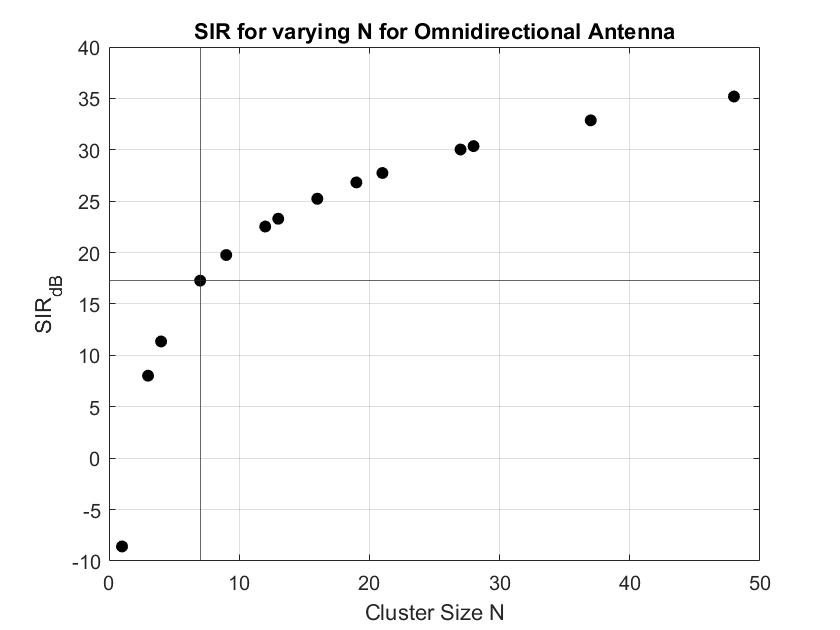

clf; figure(); hold on, box on, grid on;
scatter(N_arr, SIR_arr, "black", "filled");
xlabel("Cluster Size N"); ylabel("SIR_d_B");
title("SIR for varying N for Omnidirectional Antenna");
yline(opt_SIR);
xline(opt_N);

Therefore, we use N = 7 that gets us above the SIR threshold by 2+ decibels. 

### 120 Degree Sectoring

opt_N = 100;
N_arr = []; SIR_arr = [];
for i = 0:4
    for j=1:4
        N = (i^2) + (i*j) + (j^2);
        Q_factor = sqrt(3*N);
        SIR_computed = 1 / (((Q_factor^beta) + ...
                           ((Q_factor+0.7)^beta)));
        SIR_computed = 10*log10(SIR_computed);
        N_arr = [N_arr N];
        SIR_arr = [SIR_arr SIR_computed];
        if SIR_computed>15
            temp_N = N;
            if  temp_N < opt_N
                opt_N = temp_N;
                opt_SIR = SIR_computed;
            end
        end
    end
end
opt_N 

opt_N = 3

opt_SIR

opt_SIR = 17.5248

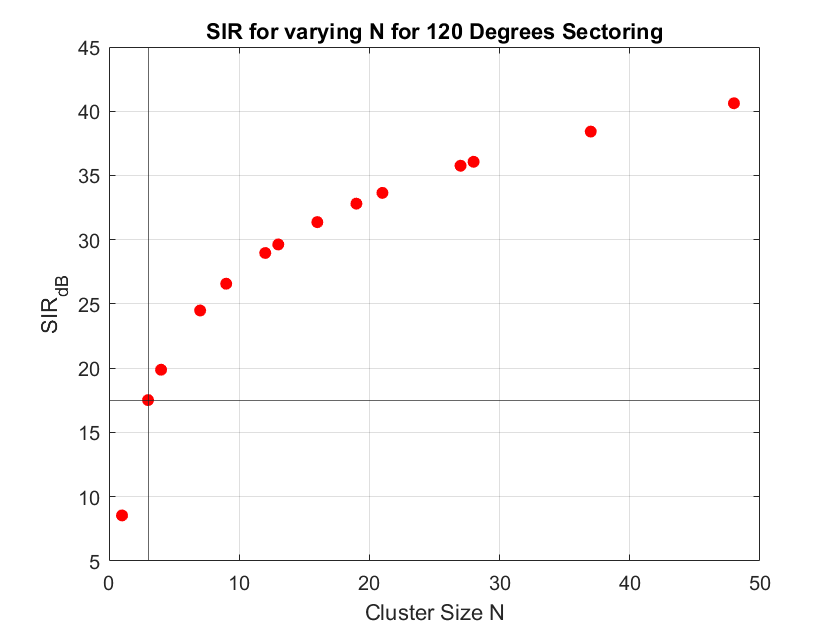

figure(); hold on, box on, grid on;
scatter(N_arr, SIR_arr, "red", "filled");
xlabel("Cluster Size N"); ylabel("SIR_d_B");
title("SIR for varying N for 120 Degrees Sectoring");
yline(opt_SIR);
xline(opt_N);

### 60 Degree Sectoring

opt_N = 100;
N_arr = []; SIR_arr = [];
for i = 0:4
    for j=1:4
        N = (i^2) + (i*j) + (j^2);
        Q_factor = sqrt(3*N);
        SIR_computed = 1 / ((Q_factor+0.7)^beta);
        SIR_computed = 10*log10(SIR_computed);
        N_arr = [N_arr N];
        SIR_arr = [SIR_arr SIR_computed];
        if SIR_computed>15
            temp_N = N;
            if  temp_N < opt_N
                opt_N = temp_N;
                opt_SIR = SIR_computed;
            end
        end
    end
end
opt_N 

opt_N = 1

opt_SIR

opt_SIR = 15.4389

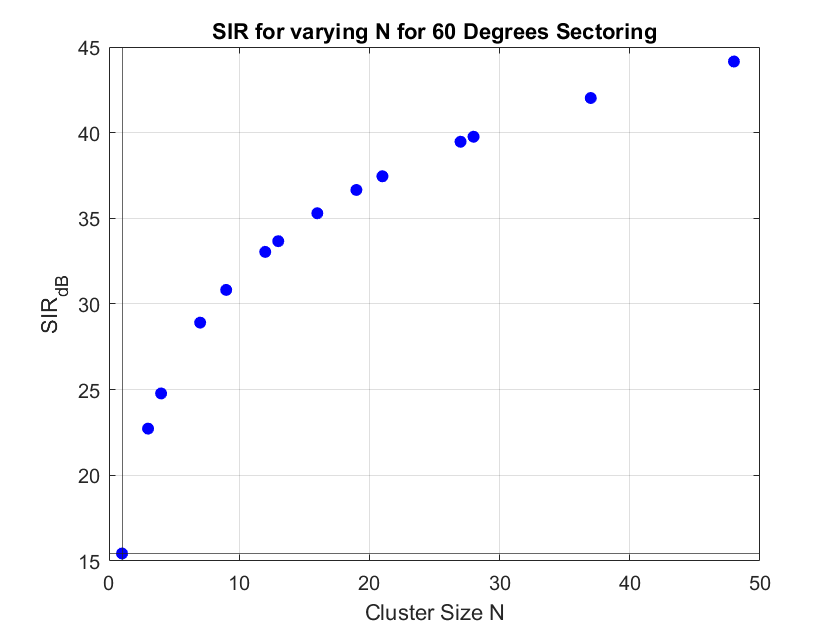

figure(); hold on, box on, grid on;
scatter(N_arr, SIR_arr, "blue", "filled");
xlabel("Cluster Size N"); ylabel("SIR_d_B");
title("SIR for varying N for 60 Degrees Sectoring");
yline(opt_SIR);
xline(opt_N);

Let's look at the cellular schemes of parts b and c. We have N = 3 for 120 degrees of separation; and N = 1 for 60 degrees of separation. The frequency reuse ratio for system b would be 1/3 whereas that for system c will be 1/1. From the cellular structures; we know that the total system capacity is equal to kNM; where k is the number of channels per cell; N is the number of cells in a cluster and M is the number of repeated clusters in the system. 

By principle; when N lowers, for the same area of coverage; we would have more repitions M and therefore a better  capacity. However, since the co-channel reuse ratio = D/R = sqrt(3*N), a lower number of N provides a lower channel reuse ratio; and therefore more co-channel interference. While system c is looking stellar at the moment, we must look at the idea of sectoring in detail. A major aspect of sectoring is the decrease in trunking gain. More sectoring makes less channels per sector and therefore decreases the overall capacity of the system. For 120 degrees, we have a better trunking efficiency than the 60 degrees sectoring system. Keeping these in view; we would use the system of part B to improve our SIR.

## **Problem 3:**

Assume a receiver is located 10km from a 50W transmitter. The carrier frequency is 6GHz and the free space propagation is assume, Gt=1 and Gr=1.

clear
d = 10*1000;
Pt = 50; 
freq = 6*10^9;
lambda = physconst('LightSpeed')/freq;
Gt = 1; Gr = 1;

### Find the power at the receiver

Pr = (Pt*Gt*Gr) / ((4*pi*d/lambda)^2) % in Watts

Pr = 7.9048e-12

10*log10(Pr) % in dB

ans = -111.0211

### Find the magnitude of E-field at the receiver antenna

flux = (Pt*Gt) / (4*pi*d^2) ;
magnitude = sqrt(flux*120*pi)

magnitude = 0.0039

### What is the receiver power in dBm?

10*log10(Pr/(10^-3)) % in dBm

ans = -81.0211

### If the receiver sensitivity is -96dBm, would the receiver be able to decode the message?

Yes, the received signal strength is -81 dBm and the receiver can sense -96 dBm

## **Problem 4**: 

A brief measurement campaign indicates that the median propagation loss at 420 MHz in a mid-size city can be modeled by the following path loss equation

 

i.e., the path loss exponent is β = 2.8 and there is a 25 dB fixed loss. 

PL_dash = 25; % dB
freq = 420 * 10^6; % Hertz
lambda = physconst('LightSpeed')/freq; % meters
L = @(d, beta) (PL_dash + (10*beta*log10(d)))

L = function_handle with value:
    @(d,beta)(PL_dash+(10*beta*log10(d)))


### Assuming a cell phone receiver sensitivity of -95 dBm, what transmitter power is required to service a circular area of radius 10 km?                            

PL_at_10km = L(10*1000, 2.8)

PL_at_10km = 137

% Pr = Pt - L 
Pt = (-95 - 30 ) + PL_at_10km % (dB)  

Pt = 12

### Suppose the measurements were optimistic and β = 3.1 is more appropriate. What is the corresponding increase in transmit power (in decibels) that would be required? 

PL_at_10km = L(10*1000, 3.1)

PL_at_10km = 149

% Pr = Pt - L 
Pt = (-95 - 30 ) + PL_at_10km % (dB)  

Pt = 24

### If log-normal shadowing is present with σ = 8 dB, how much additional transmit power is required to ensure 10% thermal noise outage at a distance of 10 km?

P_outage = 0.1; % 10%
P_coverage = 1 - P_outage;
Q_inv = @(P_coverage) (qfuncinv(P_coverage));
threshold = @(Q_inv, mean, deviation) ...
             ((Q_inv * deviation)+mean);
thres = threshold(Q_inv(P_coverage), -1*PL_at_10km, 8) 

thres = -159.2524

margin = thres - (-1*PL_at_10km)

margin = -10.2524

      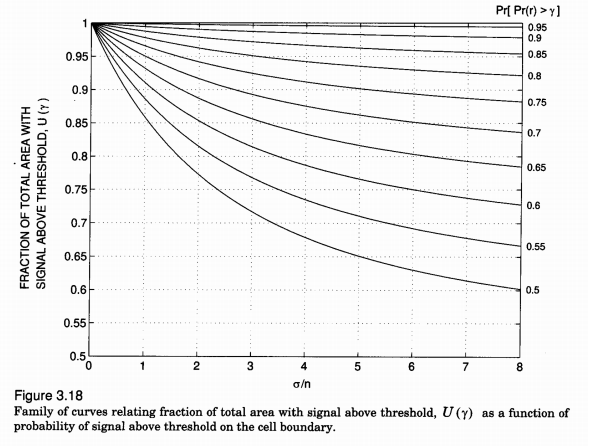

#### For n = 3.1

deviation_by_n = 8/3.1

deviation_by_n = 2.5806

As seen from the graph above; 2.58 on the x axis for the curve for P(coverage) = 0.9

intersects the y axis at approximately 0.98. Therefore;

Percentage_Area = 0.98;


#### For n = 2.8

The same method can be used to estimate the percentage area of coverage for n = 2.8

deviation_by_n = 8/2.8

deviation_by_n = 2.8571

Percentage_Area = 0.97;

## **Problem 5:**

Design and create a computer program that produces an arbitrary number of samples of propagation pathloss using a d^n pathloss model with lognormal shadowing. Your program is a radio propagation simulator, and should use, as inputs, the T-R separation, frequency, the pathloss exponent, the standard deviation of the log-normal shadowing, the close-in-reference distance, and the number of desired predicted samples. Your program should provide a check that insures that the input T-R separation is equal to or exceeds the specified input close-in-reference distance, and should provide a graphical output of the produced samples as a function of pathloss and distance ( this is called a scatter plot).

Distance 0 is less than the close-in-reference distance 3
Distance 1 is less than the close-in-reference distance 3
Distance 2 is less than the close-in-reference distance 3


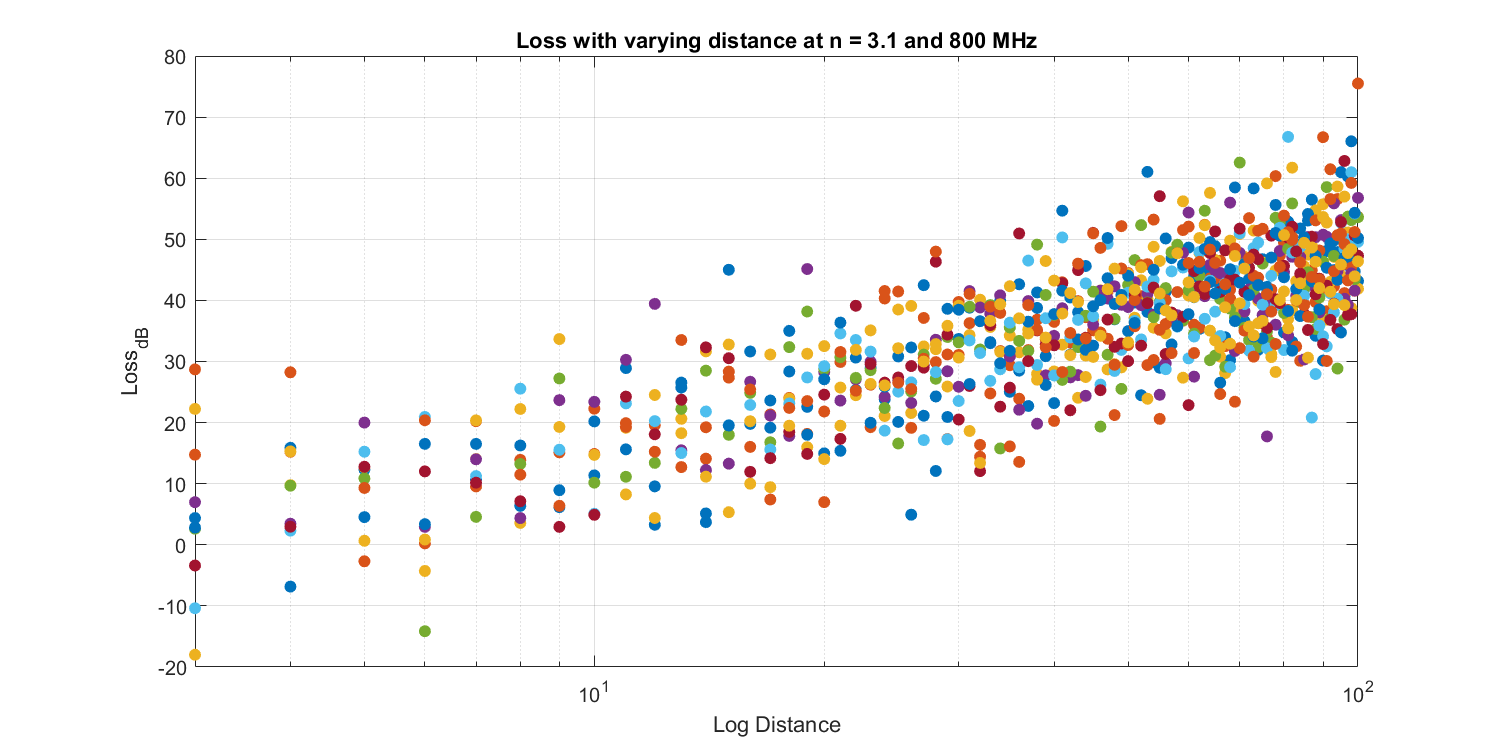

clear
data = simulation([0:100], 8*10^6, 3.1, 8, 3, 10);

Verify the accuracy of your computer program by running it for 50 samples at each of 5 different T-R separation distances (a total of 250 predicted pathloss values), and determine the best fit pathloss exponent and the standard deviation about the mean pathloss exponent of the predicted data using the techniques as described in example in the class. 

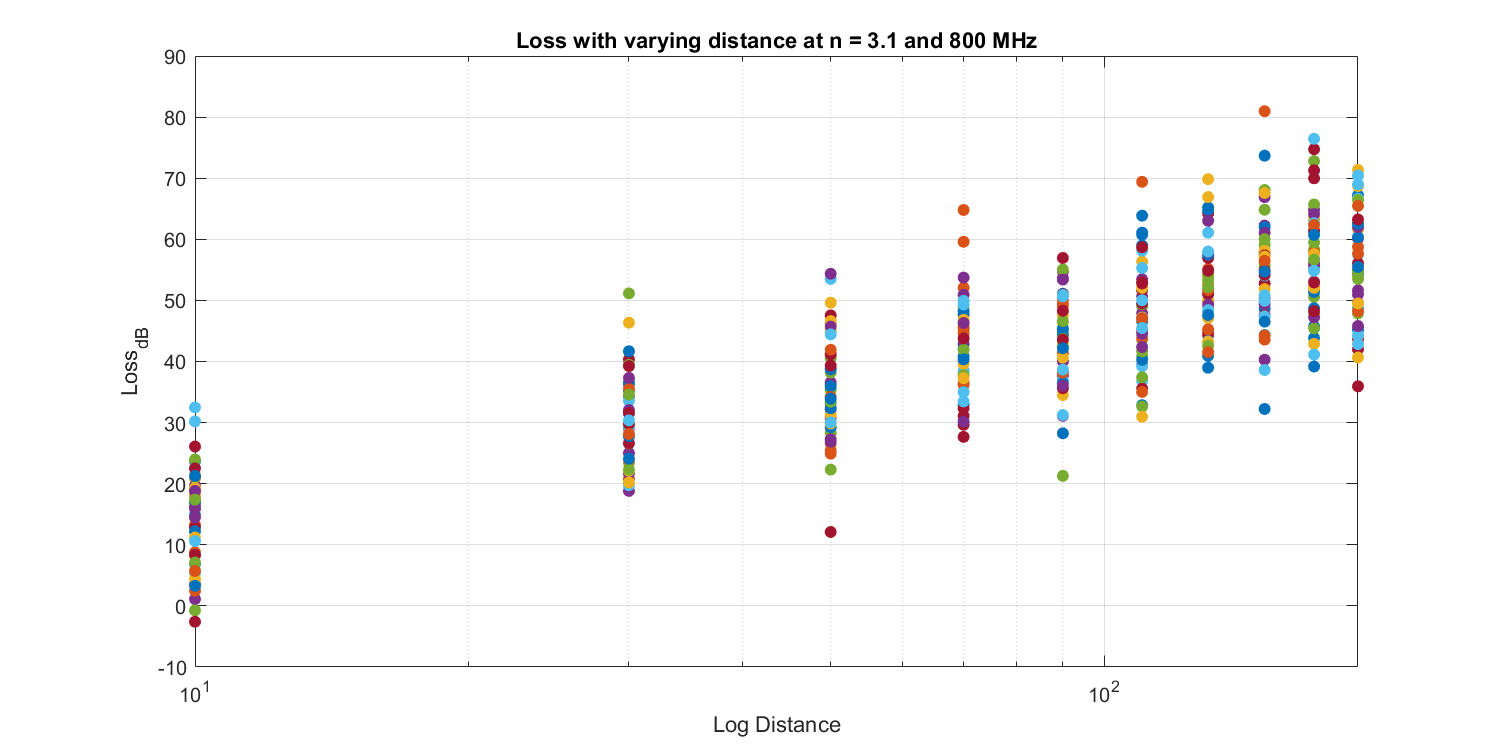

clear
d = [10:20:200];
samples = 50;
true_ple = 3.1;
data = simulation(d, 8*10^6, true_ple, 8, 3, samples);

Draw the best fit mean pathloss model on the scatter plot to illustrate the fit of the model to the predicted values. You will know your simulator is working if the best fit pathloss model and the standard deviation for your simulated data is equal to the parameters you specified as inputs to your simulators.

### Accuracy Check

x_arr = [];
y_arr = [];

for i=1:length(d)
    temp = zeros(1, length(data(:, i)));
    temp = temp + 10*log10(d(i));
    x_arr = [x_arr; temp'];
    y_arr = [y_arr; data(:, i)];
end

mdl = fitlm(x_arr,y_arr)   

mdl = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat       pValue   
                   ________    ________    _______    ___________

    (Intercept)    -18.915       1.8498    -10.225     2.0864e-22
    x1              3.2971     0.096389     34.206    8.0955e-133


Number of observations: 500, Error degrees of freedom: 498
Root Mean Squared Error: 8.14
R-squared: 0.701,  Adjusted R-Squared: 0.701
F-statistic vs. constant model: 1.17e+03, p-value = 8.1e-133

The parameter values are 3.096 and -14.717 [ values may change in further simulations ] . The former is the slope of the line between PL (dB) and Log Distance. The slope of this line gives the path loss exponent. We input the path loss exponent as 3.1; therefore our model has an inaccuracy of: 

Accuracy in the path loss exponent = 

Error_Percentage = 100*(abs(true_ple - mdl.Coefficients.Estimate(2))/true_ple)

Error_Percentage = 6.3580

The root mean squared error of the model provides the standard deviation of shadowing. 

mdl.RMSE

ans = 8.1403

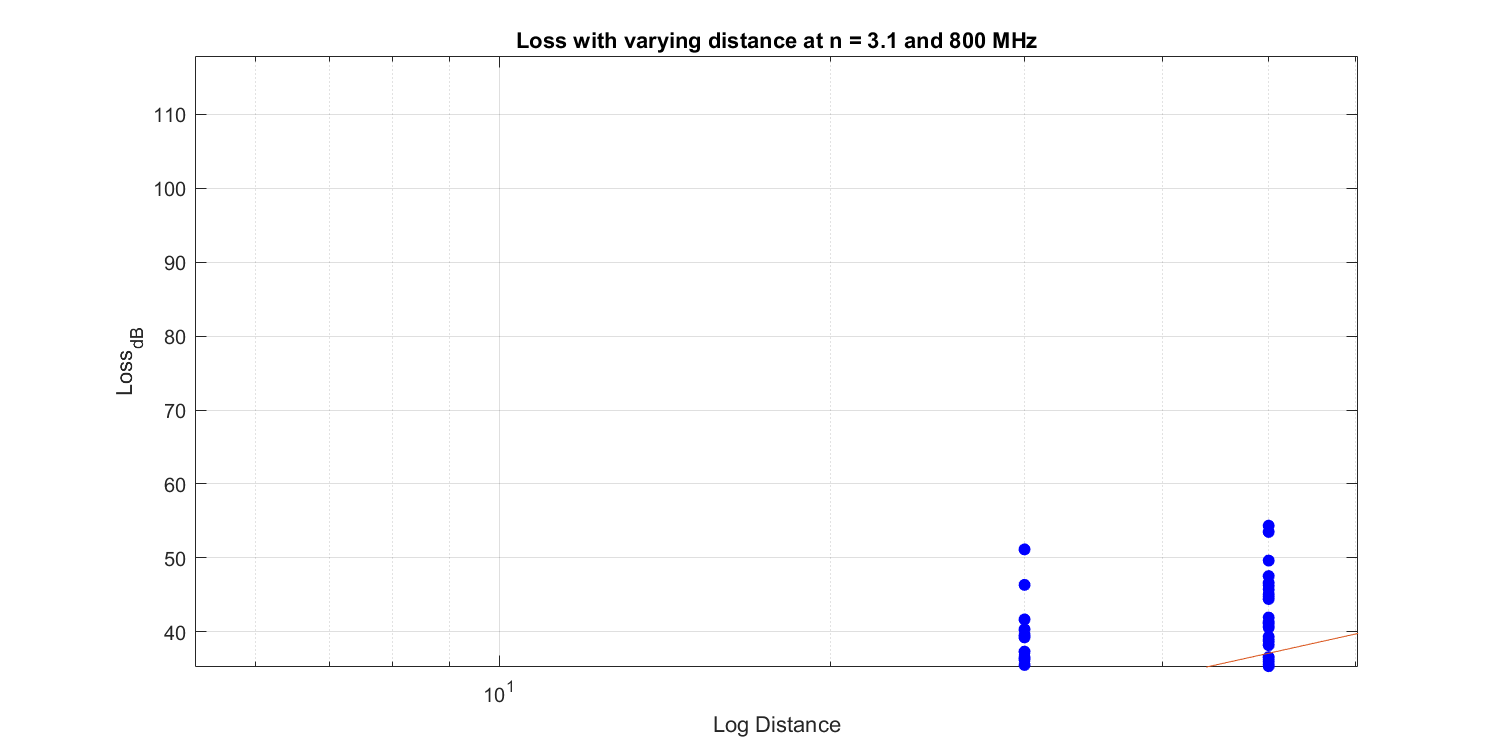

clf
figure(), hold on, box on, grid on;
set(gcf,'Position',[0 0 1000 500]);
%set(gca, 'YScale', 'log');
set(gca, 'XScale', 'log');

for j = 1:samples
    scatter(d, data(j,:), "filled", 'b'); 
end
plot(10.^(x_arr/10), predict(mdl, x_arr))
xlabel("Log Distance"); 
ylabel("Loss_d_B");
title("Loss with varying distance at n = 3.1 and 800 MHz");

## Helper Functions

function data = simulation(d, f, ple, std, d0, samples)

for i=d
    if i < d0
        d = d(d~=i);
        disp("Distance " + num2str(i) + ...
             " is less than the close-in-reference distance " + num2str(d0))
    end
end

PL_dash = @(d, ple, f) (ple*10*log10(4*pi*d*f/physconst('LightSpeed')));
X = @(std, samples) (std*randn(samples,1));
PL = @(d, ple, f, std, d0, samples) ...
           (PL_dash(d0, ple, f) + (10*ple*log10(d/d0)) + X(std, samples));

data = [];
for i = d
data = [data PL(i, ple, f, std, d0, samples)];
end       

clf
figure(), hold on, box on, grid on;
set(gcf,'Position',[0 0 1000 500]);
%set(gca, 'YScale', 'log');
set(gca, 'XScale', 'log');

for j = 1:samples
    scatter(d, data(j,:), "filled"); 
end

xlabel("Log Distance"); 
ylabel("Loss_d_B");
title("Loss with varying distance at n = 3.1 and 800 MHz");
end